# Bootcamp Day 1

## Startups

restoredefaultpath
addpath('/usr/local/MATLAB/toolboxes/fieldtrip/')
ft_defaults
addpath(genpath('/usr/local/MATLAB/toolboxes/hcn_toolbox'))
addpath(genpath('/usr/local/MATLAB/toolboxes/fieldtrip/FieldtripBootcamp/'))

% restoredefaultpath
% cd yourdefaultfieldtriplocation
% addpath(pwd)
% ft_defaults

## L1 - Introduction

Pangea bier cafe Thurs @ 7pm (2743 Franklin Blvd)

Ignacio Saez, isaez@ucdavis.edu

Robert Oostenveld

Signals in the brain

- Scalp potentials associated with post-synaptic potentials in pyramidal neurons (excitatory and inhibitory inputs). Spikes are small, fleeting, unsunchronized. Therefore they cancel out with larger electrodes. EEG/iEEG activity is more synchronized, larger, longer, thus easier to measure. Aligned pyramidal cells are primarily what we measure in EEG/iEEG. Poorly aligned neurons cause signal cancellation at the electrode level.

- Right hand rule relationship: direction of electrical flow and generated magnetic flow

Volume conduction

- Generated current passes through all tissues nad can be recorded at a potential difference either close to or far from source

- Conductivity vs. propagation: passive electrical flow vs. directed activity due to signal transmission among neurons

- Models assume that tissue is purely resistive and not capacitive (which is vaid for recordings of 100s of Hz)

Definitions

- electrode = point of contact between acquisition sstem and recording site

- channel = output of analog-to-digital converter (in the amplifier). channels can refer to 2 electrodes (reference electrode). signal is interpreted in channel

- in MEG = sensors in fixed arrangement relative to head and three magnetic coil fiducials that are placed on known locations on head. thus, we can determine sensor locations relative to head

EEG

- 10-20 system most common based on anatomical landmarks

- eeg electrodes a priori placed relative to head

- electrode caps only approximate landmark-based locations - need to record positions with Polhemus digitizer or optical 3-D scanner (or assume they are close to landmarks). may be company that makes cheap 3d scanning tehcnology (works with ipad/tablet)

ECoG and sEEG

- grids, strips, depths

- position can be determined from a prior stereotaxic planning, surgical drawings and/or photos, post-surgical MR/CT scans

Suppression of unwanted signals (noise)

- MEG - earth's and other magnetic fields affect signals. human sigals 10e-12, earth 10e-5. coil design is important for noise reduction. most sensitive at the sides of the brain source. environmental noise is large and homogenous. magneticall shielded room and coild design automatically cancels out these large homogenouse noise based on dual coil design (brain signal reaches one coil in dual, but not others). different geometries of magnetometers determine sensitivity profiles relative to source location; therefore spatial distribution of signals will be different

- EEG - much blurrier than MEG signals. effected by common body potentials on all electrodes. suppressed by ground electrode in amplifier design (common mode rejection "CMRR"). ground electrode removes larger potentials common across electrodes. gorund is placed such that all potential differences are as small as possible, then we amplify difference signals and digitize. N-channel system requires N+2 electrodes (1 is ground electrode, 1 used for reference). reference schemes: common reference, average reference, driven-right-leg (CMS/DRL) referene, bipolar reference. choice of reference influences sensitivities to other distant sources. voltage difference in channel is due to potential electrode of interest and reference. online reference is not electricall neutral, thus offline re-reference is often used as well. electrode locations affect spatial sensitivity distribution and in turn should determine where and how you reference. 

- different spatial mixing of signals based on electrode placement also affects temporal dynamics

analyzing signals with fieldtrip

- time course (ERP), spectral (power spectrum), temporal changes in power (time-frequency response), spatial distribution

- evoked activity - averaged event-aligned activity

- induced activity - activity in response to event, but not temporally aligned to event

- superposition of source activity 

- separating activity of sources: teporal aspects: latency differences, potential differences, time-series filtering. spatial aspects: re-referenceing, volume conduction

- dataout = function(cfg,datain,...) -> cfg = configuration structure (human readable format)

- rawData = data structure with labels, data by trial, time by trial, Fs,

- event related response = label, average signal, variance, time, dimord (e.g., 'chan_time' means channels x time for rows x columns)

- can use output cfg from functions to get a record of the analysis steps taken

## H1 - Trial Selection and preprocessing

%%%% L2 - Clinical aspects of intracranial recordings
% from http://www.fieldtriptoolbox.org/tutorial/preprocessing/

There are largely two alternative approaches for preprocessing, which  especially differ in the amount of memory required. The first approach  is to read all data from the file into memory, apply filters, and  subsequently cut the data into interesting segments. The second approach is to first identify the interesting segments, read those segments from the data file and apply the filters to those segments only. The  remainder of this tutorial explains the second approach, as that is the  most appropriate for large data sets such as the EEG data used in this  tutorial. The approach for reading and filtering continuous data and  segmenting afterwards is explained in [another tutorial](http://www.fieldtriptoolbox.org/tutorial/continuous).

Preprocessing involves several steps including identifying individual trials from the dataset, filtering and artifact rejections. This  tutorial covers how to identify trials using the trigger signal.  Defining data segments of interest can be done according to a specified  trigger channel or according to your own criteria when you write your  own trial function. Examples for both ways are described in this  tutorial, and both ways depend on [**ft_definetrial**](http://www.fieldtriptoolbox.org/reference/ft_definetrial).

Using the FieldTrip function [**ft_definetrial**](http://www.fieldtriptoolbox.org/reference/ft_definetrial) you can define the pieces of data that will be read in for  preprocessing. The output of ft_definetrial is a configuration structure containing the field cfg.trl. This is a matrix representing the relevant parts of the  raw datafile which are to be selected for further processing. Each row  in the trl-matrix represents a single epoch-of-interest, and the  trl-matrix has at least 3 columns. The first column defines (in samples) the beginpoint of each epoch with respect to how the data are stored in the raw datafile. The second column defines (in samples) the endpoint  of each epoch, and the third column specifies the offset (in samples) of the first sample within each epoch with respect to timepoint 0 within  that epoch.

% fully incongruent trials
cfg = [];
cfg.dataset = fullfile('Fieldtrip/Subject01/Subject01.ds');
cfg.trialfun                = 'ft_trialfun_general'; % this is the default
cfg.trialdef.eventtype      = 'backpanel trigger';
cfg.trialdef.eventvalue     = 3; % the value of the stimulus trigger for fully incongruent (FIC).
cfg.trialdef.prestim        = 1; % in seconds
cfg.trialdef.poststim       = 2; % in seconds

cfg = ft_definetrial(cfg);

evaluating trialfunction 'ft_trialfun_general'
reading the header from 'Fieldtrip/Subject01/Subject01.ds/Subject01.res4'



readCTFds: You are reading CTF data for use with a software-application tool
	that is not manufactured by VSM MedTech Ltd. and has not received marketing
	clearance for clinical applications.  If CTF MEG data are processed by this tool,
	they should not be later employed for clinical and/or diagnostic purposes.



 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In ft_trialfun_general at line 84
 In ft_definetrial at

 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In ft_read_event at line 513
 In ft_trialfun_gene

This results in a cfg.trl in which the beginning, the trigger offset  and the end of each trial relative to the beginning of the raw data is  defined.

The output of [**ft_definetrial**](http://www.fieldtriptoolbox.org/reference/ft_definetrial) can be used for [**ft_preprocessing**](http://www.fieldtriptoolbox.org/reference/ft_preprocessing).

cfg.channel    = {'MEG' 'EOG'};
cfg.continuous = 'yes';
dataFIC = ft_preprocessing(cfg);

 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In ft_preprocessing at line 397

processing channel { 'MLC11' 'MLC12' 'MLC13' 'MLC14' 'MLC15' 'MLC21' 'MLC22' 'MLC23' 'MLC24' 'MLC31' 'MLC32' 'MLC33' 'MLC41' 'ML

save PreprocData dataFIC

The most important fields are dataFIC.trial containing the individual  trials and dataFIC.time containing the time vector for each trial.

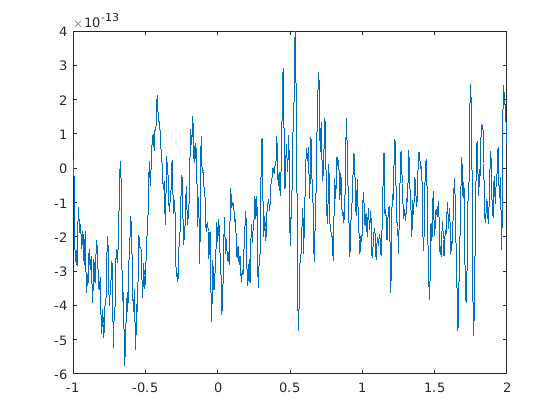

% visualize single-trial data (trial 1)
plot(dataFIC.time{1}, dataFIC.trial{1}(130,:))

The preprocessing steps will be repeated for the other conditions as well.

% need to reset cfg for each separate call to ft functions. cfg is samed in
% output of function in structure field 'cfg'

% initially incongruent trials
cfg                         = [];
cfg.dataset                 = fullfile('Fieldtrip/Subject01/Subject01.ds');
cfg.trialdef.eventtype      = 'backpanel trigger';
cfg.trialdef.eventvalue     = 5; % the value of the stimulus trigger for initially congruent (IC).
cfg.trialdef.prestim        = 1; % in seconds
cfg.trialdef.poststim       = 2; % in seconds

cfg = ft_definetrial(cfg);

 In ft_definetrial at line 145

evaluating trialfunction 'ft_trialfun_general'
reading the header from 'Fieldtrip/Subject01/Subject01.ds/Subject01.res4'


 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In ft_trialfun_general at line 84
 In ft_definetrial at

 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In ft_read_event at line 513
 In ft_trialfun_gene


cfg.channel    = {'MEG' 'EOG'};
cfg.continuous = 'yes';
dataIC = ft_preprocessing(cfg);

 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In ft_preprocessing at line 397

processing channel { 'MLC11' 'MLC12' 'MLC13' 'MLC14' 'MLC15' 'MLC21' 'MLC22' 'MLC23' 'MLC24' 'MLC31' 'MLC32' 'MLC33' 'MLC41' 'ML


save PreprocData dataIC -append

% fully congruent trials
cfg                         = [];
cfg.dataset                 = fullfile('Fieldtrip/Subject01/Subject01.ds');
cfg.trialdef.eventtype      = 'backpanel trigger';
cfg.trialdef.eventvalue     = 9; % the value of the stimulus trigger for fully congruent (FC).
cfg.trialdef.prestim        = 1; % in seconds
cfg.trialdef.poststim       = 2; % in seconds

cfg = ft_definetrial(cfg);

 In ft_definetrial at line 145

evaluating trialfunction 'ft_trialfun_general'
reading the header from 'Fieldtrip/Subject01/Subject01.ds/Subject01.res4'


 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In ft_trialfun_general at line 84
 In ft_definetrial at

 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In ft_read_event at line 513
 In ft_trialfun_gene


cfg.channel    = {'MEG' 'EOG'};
cfg.continuous = 'yes';
dataFC = ft_preprocessing(cfg);

 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In ft_preprocessing at line 397

processing channel { 'MLC11' 'MLC12' 'MLC13' 'MLC14' 'MLC15' 'MLC21' 'MLC22' 'MLC23' 'MLC24' 'MLC31' 'MLC32' 'MLC33' 'MLC41' 'ML

save PreprocData dataFC -append

## Use your own function for trial selection

There are often cases in which it is not sufficient to define a trial  only according to a given trigger signal. For instance you might want to accept or reject a trial according to a button response recorded by the trigger channel as well. Another example might be that you want the  signals from the EMG or A/D channel being part of the trial selection.  In those cases it is necessary to define a specialized function for  trial selections. Below is an example which can be adapted to your  needs.

cfg = [];
cfg.dataset              = fullfile('Fieldtrip/Subject01/Subject01.ds');
cfg.trialfun             = 'mytrialfun';     % it will call your function and pass the cfg
cfg.trialdef.eventtype  = 'backpanel trigger';
cfg.trialdef.eventvalue = [3 5 9];           % read all conditions at once
cfg.trialdef.prestim    = 1; % in seconds
cfg.trialdef.poststim   = 2; % in seconds

cfg = ft_definetrial(cfg);

evaluating trialfunction 'mytrialfun'


 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In mytrialfun at line 10
 In ft_definetrial at line 180

 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In ft_read_event at line 513
 In mytrialfun at li


cfg.channel = {'MEG' 'STIM'};
dataMytrialfun = ft_preprocessing(cfg);

 In ft_estimate_units at line 52
 In ft_determine_units at line 83
 In ft_datatype_sens at line 372
 In ft_datatype_sens at line 158
 In ft_read_header at line 2657
 In ft_preprocessing at line 397

processing channel { 'STIM' 'MLC11' 'MLC12' 'MLC13' 'MLC14' 'MLC15' 'MLC21' 'MLC22' 'MLC23' 'MLC24' 'MLC31' 'MLC32' 'MLC33' 'MLC

When you do not specify cfg.trialfun, [**ft_definetrial**](http://www.fieldtriptoolbox.org/reference/ft_definetrial) will call a function named trialfun_general as default. Then trials  will be defined as we have seen it in the earlier section (Reading and  preprocessing the interesting trials).

The output dataMytrialfun now contains all of the trials of the three conditions (since we specified all three triggers values: 3, 5 and 9).  It also contains a field dataMytrialfun.trialinfo, which contains the  4th column of the trl (trial definition) which contains the trigger  values, i.e., it tells you to which condition each trial belong

## Preprocessing of EEG data and computing ERPs

In FieldTrip the preprocessing of data refers to the reading of the  data, segmenting the data around interesting events such as triggers,  temporal filtering and optionally rereferencing. The [**ft_preprocessing**](http://www.fieldtriptoolbox.org/reference/ft_preprocessing) function takes care of all these steps, i.e., it reads the data and applies the preprocessing options.

## **Defining trials**

For memory efficiency (especially relevant for large datasets), with  FieldTrip we commonly use the strategy to only read in those segments of data that are of interest. This requires first to define the segments  of interest (the trials) and subsequently to read them in and preprocess them. It is also possible to read in the whole continuous data, and  segment the data in memory [(see here)](http://www.fieldtriptoolbox.org/tutorial/continuous).

Instead of using the default ‘trialfun_general’ function with [**ft_definetrial**](http://www.fieldtriptoolbox.org/reference/ft_definetrial), we will use a custom ‘trialfun_affcog’ that has been written  specifically for this experiment. This custom function reads markers  from the EEG record and identifies trials that belong to condition 1  (positive-negative judgement) or 2 (animal-human judgement). The  function is available along with the data.

addpath('/usr/local/MATLAB/toolboxes/fieldtrip/FieldtripBootcamp/Fieldtrip/preprocessing_erp')
cfg              = [];
cfg.trialfun     = 'trialfun_affcog';
cfg.headerfile   = fullfile('Fieldtrip/preprocessing_erp/s04.vhdr');
cfg.datafile     = fullfile('Fieldtrip/preprocessing_erp/s04.eeg');
cfg = ft_definetrial(cfg);

evaluating trialfunction 'trialfun_affcog'
found 961 events
created 192 trials
the call to "ft_definetrial" took 0 seconds and required the additional allocation of an estimated 0 MB


After the call to [**ft_definetrial**](http://www.fieldtriptoolbox.org/reference/ft_definetrial), the cfg now not only stores the dataset name, but also the definition  of the segments of data that will be used for further processing and  analysis. The first column is the begin sample, the second the end  sample, the third the offset and the fourth contains the condition for  each trial (1=affective, 2=ontological).

disp(cfg.trl(1:10,:))

       52441       53041        -100           2
       56740       57340        -100           1
       61845       62445        -100           1
       66383       66983        -100           2
       70402       71002        -100           1
       74747       75347        -100           1
       78679       79279        -100           2
       82544       83144        -100           1
       86610       87210        -100           1
       91721       92321        -100           2



## **Pre-processing and re-referencing**

In this raw BrainVision dataset, the signal from all electrodes is  recorded unipolar and referenced to an electrode on the left mastoid. We want the signal to be referenced to linked (left and right) mastoids.  During the acquisition an ‘RM’ electrode (number 32) was placed on the  right mastoid and recorded along with all EEG channels.

To re-reference the data we use the `cfg``.``implicitref` option of [**ft_preprocessing**](http://www.fieldtriptoolbox.org/reference/ft_preprocessing) to add the implicit reference channel ‘LM’ (the left mastoid) to the  data representation as a channel with all zeros, and subsequently use  the `cfg``.``refchannel` and `cfg``.``reref` options to subtract the mean of the two mastoid channels (‘LM’ and ‘RM’) from all channels.

Now call pre-processing using the cfg output that resulted from [**ft_definetrial**](http://www.fieldtriptoolbox.org/reference/ft_definetrial):

% Baseline-correction options
cfg.demean          = 'yes';
cfg.baselinewindow  = [-0.2 0];

% Fitering options
cfg.lpfilter        = 'yes';
cfg.lpfreq          = 100;

% Re-referencing options - see explanation above
cfg.implicitref   = 'LM';
cfg.reref         = 'yes';
cfg.refchannel    = {'LM' 'RM'};

data = ft_preprocessing(cfg);

processing channel { '1' '2' '3' '4' '5' '6' '7' '8' '9' '10' '11' '12' '13' '14' '15' '16' '17' '18' '19' '20' '21' '22' '23' '24' '25' '26' '27' '28' '29' '30' '31' 'RM' '33' '34' '35' '36' '37' '38' '39' '40' '41' '42' '43' '44' '45' '46' '47' '48' '49' '50' '51' '52' '53' '54' '55' '56' '57' '58' '59' '60' 'LEOG' '62' '63' '64' }
reading and preprocessing
reading and preprocessing trial 192 from 192

the call to "ft_preprocessing" took 2 seconds and required the additional allocation of an estimated 51 MB


Try [**ft_databrowser**](http://www.fieldtriptoolbox.org/reference/ft_databrowser) now to visualize the data segments that were read into memory.

the input is raw data with 65 channels and 192 trials
detected   0 visual artifacts


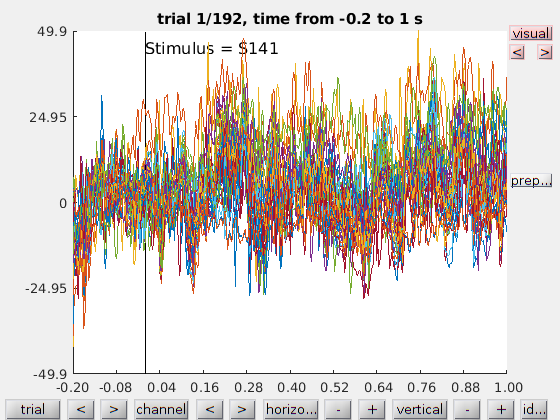

the call to "ft_databrowser" took 2 seconds and required the additional allocation of an estimated 2 MB


cfg = [];  % use only default options
ft_databrowser(cfg, data);

You can also use [**ft_databrowser**](http://www.fieldtriptoolbox.org/reference/ft_databrowser) to visualize the continuous data that is stored on disk. The data will be read on the fly:

detected   0 visual artifacts


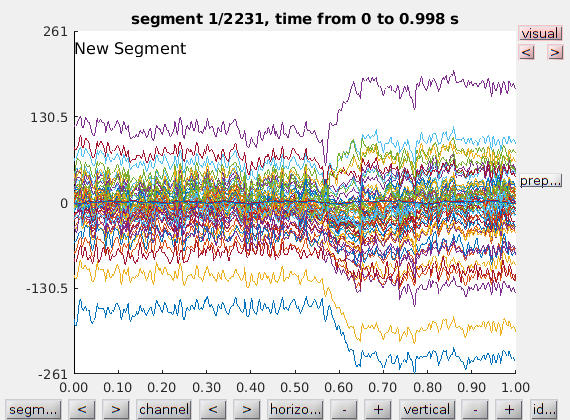

the call to "ft_databrowser" took 1 seconds and required the additional allocation of an estimated 9 MB


cfg         = [];
cfg.dataset = fullfile('Fieldtrip/preprocessing_erp/s04.vhdr');
% cfg.viewmode = 'vertical'
ft_databrowser(cfg);

FieldTrip data structures are intended to be ‘lightweight’, in the sense that the internal MATLAB arrays can be transparently accessed. If you wanted to, you could plot a single trial with default MATLAB function

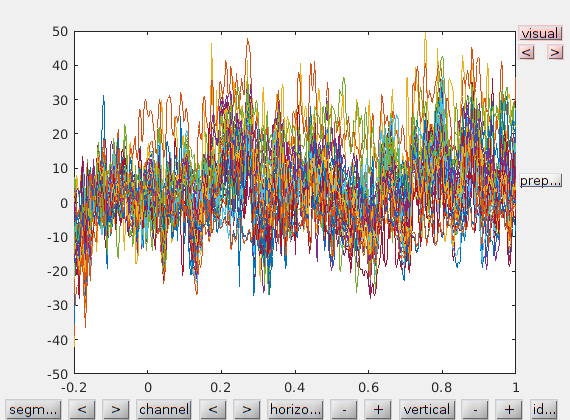

plot(data.time{1}, data.trial{1});

We now continue with re-referencing to extract the bipolar EOG signal  from the data. In the BrainAmp acquisition system, all channels are  measured relative to a common reference. For the horizontal EOG we will  compute the potential difference between channels 57 and 25 (see the  plot of the layout and the figure below). For the vertical EOG we will  use channel 53 and channel “LEOG” which was placed below the subjects’  left eye (not pictured on the layout). (Some acquisition systems, such as Biosemi, allow for direct bipolar  recording of EOG. The following re-referencing step to obtain the EOG  channels is not needed when working with bipolar data.)

% EOGV channel
cfg              = [];
cfg.channel      = {'53' 'LEOG'};
cfg.reref        = 'yes';
cfg.implicitref  = []; % this is the default, we mention it here to be explicit
cfg.refchannel   = {'53'};
eogv             = ft_preprocessing(cfg, data);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 192 from 192

the call to "ft_preprocessing" took 0 seconds and required the additional allocation of an estimated 0 MB




% only keep one channel, and rename to eogv
cfg              = [];
cfg.channel      = 'LEOG';
eogv             = ft_selectdata(cfg, eogv);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB


eogv.label       = {'eogv'};

% EOGH channel
cfg              = [];
cfg.channel      = {'57' '25'};
cfg.reref        = 'yes';
cfg.implicitref  = []; % this is the default, we mention it here to be explicit
cfg.refchannel   = {'57'};
eogh             = ft_preprocessing(cfg, data);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
preprocessing
preprocessing trial 192 from 192

the call to "ft_preprocessing" took 1 seconds and required the additional allocation of an estimated 0 MB



% only keep one channel, and rename to eogh
cfg              = [];
cfg.channel      = '25';
eogh             = ft_selectdata(cfg, eogh);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB


eogh.label       = {'eogh'};

We now discard these extra channels that were used as EOG from the data  and add the bipolar-referenced EOGv and EOGh channels that we have just  create

% only keep all non-EOG channels
cfg         = [];
cfg.channel = setdiff(1:60, [53, 57, 25]);        % you can use either strings or numbers as selection
data        = ft_selectdata(cfg, data);

the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB



% append the EOGH and EOGV channel to the 60 selected EEG channels
cfg  = [];
data = ft_appenddata(cfg, data, eogv, eogh);

 In ft_appenddata at line 95



 In ft_appenddata at line 96

concatenating over the "chan" dimension
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_appenddata" took 0 seconds and required the additional allocation of an estimated 0 MB


You can check the channel labels that are now present in the data and use [**ft_databrowser**](http://www.fieldtriptoolbox.org/reference/ft_databrowser) to look at all data combined.

disp(data.label')

  Columns 1 through 9

    '1'    '2'    '3'    '4'    '5'    '6'    '7'    '8'    '9'

  Columns 10 through 17

    '10'    '11'    '12'    '13'    '14'    '15'    '16'    '17'

  Columns 18 through 25

    '18'    '19'    '20'    '21'    '22'    '23'    '24'    '26'

  Columns 26 through 33

    '27'    '28'    '29'    '30'    '31'    'RM'    '33'    '34'

  Columns 34 through 41

    '35'    '36'    '37'    '38'    '39'    '40'    '41'    '42'

  Columns 42 through 49

    '43'    '44'    '45'    '46'    '47'    '48'    '49'    '50'

  Columns 50 through 57

    '51'    '52'    '54'    '55'    '56'    '58'    '59'    '60'

  Columns 58 through 59

    'eogv'    'eogh'



## **Channel layout**

For topoplotting and sometimes for analysis it is necessary to know how  the electrodes were positioned on the scalp. In contrast to the sensor  arrangement from a given MEG manufacturer, the topographical arrangement of the channels in EEG is not fixed. Different acquisition systems are  designed for different electrode montages, and the number and position  of electrodes can be adjusted depending on the experimental goal. In the current experiment, so-called 64-electrodes equidistant montage  (ActiCap, BrainVision) was used.

The channel positions are not stored in the EEG dataset. You have to use a layout file; this is a .mat file that contains the 2-D positions of  the channels. FieldTrip provides a number of default layouts for  BrainVision EEG caps in the fieldtrip/template/layout directory. It is  also possible to create custom layouts (see [**ft_prepare_layout**](http://www.fieldtriptoolbox.org/reference/ft_prepare_layout) and the [layout tutorial](http://www.fieldtriptoolbox.org/tutorial/layout)). In this example we will use an existing layout file that is included with the example data.

reading layout from file mpi_customized_acticap64.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 0 MB


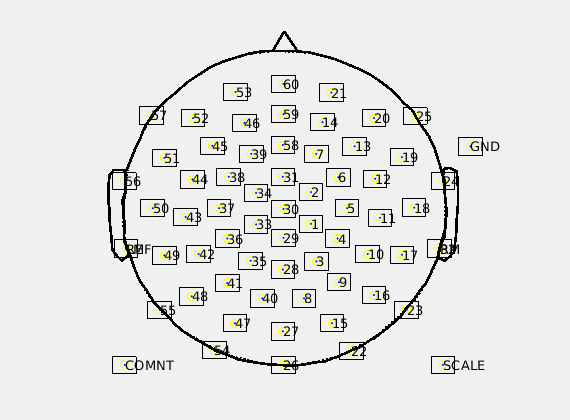

the call to "ft_layoutplot" took 1 seconds and required the additional allocation of an estimated 4 MB


cfg        = [];
cfg.layout = 'mpi_customized_acticap64.mat';
ft_layoutplot(cfg);

Note that the layout should contain correct channel labels that match  the channel labels in the data (channel labels not present in either  will not be plotted when using a given layout).

## **Artifacts**

An next important step of EEG preprocessing is detection (and rejection) of artifacts. Different approaches of dealing with artifacts are  presented in details in the [introductory tutorial on artifacts](http://www.fieldtriptoolbox.org/tutorial/artifacts), the [visual artifact removal tutorial](http://www.fieldtriptoolbox.org/tutorial/visual_artifact_rejection) and the [automatic artifact rejection removal tutorial](http://www.fieldtriptoolbox.org/tutorial/automatic_artifact_rejection). In this example script, we will use [**ft_rejectvisual**](http://www.fieldtriptoolbox.org/reference/ft_rejectvisual) function to visually inspect the data and reject the trials or channels that contain artifacts. We first will try the “channel” mode. In this  mode all trials are displayed at once allowing paging through the  channels. Then we will try the “summary” mode.

**Channel mode**

cfg        = [];
cfg.method = 'channel';
ft_rejectvisual(cfg, data)

the input is raw data with 59 channels and 192 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
showing the data per channel, all trials at once


channel 1 marked as GOOD
channel 2 marked as GOOD


channel 3 marked as GOOD


channel 4 marked as GOOD


channel 5 marked as GOOD


channel 6 marked as GOOD


channel 7 marked as GOOD


channel 8 marked as GOOD


channel 9 marked as GOOD


channel 10 marked as GOOD


channel 11 marked as GOOD


channel 21 marked as GOOD


channel RM marked as GOOD


channel 42 marked as GOOD


channel 52 marked as GOOD


channel 51 marked as GOOD


channel eogh marked as GOOD


channel eogv marked as GOOD


channel eogv marked as GOOD


channel eogv marked as GOOD


channel eogv marked as GOOD


channel eogv marked as GOOD


channel eogv marked as GOOD


channel eogv marked as GOOD


187 trials marked as GOOD, 5 trials marked as BAD
59 channels marked as GOOD, 0 channels marked as BAD
the following trials were removed: 22, 42, 126, 136, 150
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_rejectvisual" took 80 seconds and required the additional allocation of an estimated 17 MB


ans = struct with fields:
         label: {59×1 cell}
     trialinfo: [187×1 double]
    sampleinfo: [187×2 double]
         trial: {1×187 cell}
          time: {1×187 cell}
       fsample: 500
           cfg: [1×1 struct]


You can scroll to the vertical EOG channel (‘veog’, number 61) and  confirm to yourself that trials 22, 42, 126, 136 and 150 contain blinks. You can exclude a trial from the data by clicking on it. Note, however, that in this example we do not assign any output to the function.  MATLAB will create the default output “ans” variable. All the changes  (rejections) that you make will be applied to the “ans”. The “data” will remain the same, no trials will be removed!

[In [**ft_rejectvisual**](http://www.fieldtriptoolbox.org/reference/ft_rejectvisual) with cfg.method=’channel’ you can go to channel ‘43’ (note that the  channel name is ‘43’ and its number is also 43). There you will see that in trials 138 to 149 this channel is a bit more noisy, suggesting that  the electrode contact on this side of the cap was temporarily bad.  Neighboring channels also suggest that at trial 138 something happened,  perhaps a movement of the electrode cap. We are not going to deal with  this now, but it is something that you might want to keep in mind for  optional cleaning of the data with [**ft_componentanalysis**](http://www.fieldtriptoolbox.org/reference/ft_componentanalysis) and [**ft_rejectcomponent**](http://www.fieldtriptoolbox.org/reference/ft_rejectcomponent)]

**Summary mode**

The data can be also displayed in a “summary” mode, in which case the  variance (or another metric) in each channel and each trial is computed. Close the “channel” mode figure and try the “summary” mode. Note, that a new variable “data_clean” will be created now.

cfg          = [];
cfg.method   = 'summary';
cfg.layout   = 'mpi_customized_acticap64.mat';  % for plotting individual trials
cfg.channel  = [1:60];                          % do not show EOG channels
data_clean   = ft_rejectvisual(cfg, data);

the input is raw data with 59 channels and 192 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 45 MB
showing a summary of the data for all channels and trials


computing metric [-------------------|                                     ]computing metric [---------------------------------------/                 ]computing metric [---------------------------------------------------------]


184 trials marked as GOOD, 8 trials marked as BAD
58 channels marked as GOOD, 1 channels marked as BAD
the following channels were removed: 48
the following trials were removed: 22, 42, 89, 90, 92, 126, 136, 150
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 51 MB
the call to "ft_rejectvisual" took 66 seconds and required the additional allocation of an estimated 105 MB



% graph is interactive. can draw a box around outlier trials/channels and
% FT will automatically reject them and keep track of them for further
% analyses

The left lower box of Figure 4 shows the variance of the signal in  each trial. By dragging the mouse over the trials in this box you can  remove them from the plot and reject them from the data. You will see  the numbers of the rejected trials in the box on the right. You can undo the rejection by typing the trial’s number in “Toggle trial” box. You  can also plot the signal in a specific trial with “Plot trial” box.  Here, we have plotted the trial 90 - the one with the highest variance.  On the topoplot you can see drift in channel 48. You can zoom further in to this channel by dragging the mouse over it and clicking.

Rejection of trials based on visual inspection is somewhat arbitrary; it is not always easy to decide if a trial should be rejected or not.  In this exercise we suggest that you remove 8 trials with the highest  variance (trial numbers 22, 42, 89, 90, 92, 126, 136 and 150). As you  see, the trials with blinks that we saw in the “Channel” mode are among  them. To complete the rejection press “Quit” button. You get the  data_clean variable that will be used for subsequent analyses.

After removing data segments that contain artifacts, you might want to do a last visual inspection of the EEG traces.

% cfg = [];
% cfg.viewmode = 'vertical';
% ft_databrowser(cfg, data_clean);

Note that you can also use [**ft_databrowser**](http://www.fieldtriptoolbox.org/reference/ft_databrowser) to mark artifacts instead of - or in addition to - ft_rejectvisual. The artifacts marked in ft_databrowser can be removed using [**ft_rejectartifact**](http://www.fieldtriptoolbox.org/reference/ft_rejectartifact). The important difference between the two is that ft_rejectvisual can  only be used to reject complete trials, whereas ft_rejectartifact can  also be used to reject small sections from continuous data or from long  trials.

**Computing and plotting the ERPs**

We now would like to compute the ERPs for two conditions:  positive-negative judgement and human-animal judgement. For each trial,  the condition is assigned by the trialfun that we used in the beginning  when defined the trials, this information is kept with the data in  data.trialinfo.

disp(data_clean.trialinfo(1:19)')

  Columns 1 through 10

     2     1     1     2     1     1     2     1     1     2

  Columns 11 through 19

     1     1     1     2     1     1     2     2     2



FieldTrip automatically kept track of the trials with artifacts that were rejected: the `data_clean``.``trialinfo` field contains the condition code for the 184 clean trials, whereas the `data``.``trialinfo` field contained the information for the original 192 trials.

We now select the trials with conditions 1 and 2 and compute ERPs.

% use ft_timelockanalysis to compute the ERPs
cfg = [];
cfg.trials = find(data_clean.trialinfo==1);
task1 = ft_timelockanalysis(cfg, data_clean);

the input is raw data with 58 channels and 184 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_timelockanalysis" took 0 seconds and required the additional allocation of an estimated 1 MB



cfg = [];
cfg.trials = find(data_clean.trialinfo==2);
task2 = ft_timelockanalysis(cfg, data_clean);

the input is raw data with 58 channels and 184 trials
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 0 MB
the call to "ft_timelockanalysis" took 0 seconds and required the additional allocation of an estimated 0 MB


the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
reading layout from file mpi_customized_acticap64.mat
the call to "ft_prepare_layout" took 0 seconds and required the additional allocation of an estimated 1 MB


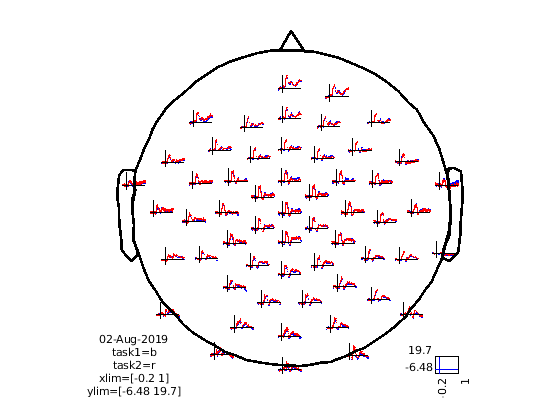

the call to "ft_multiplotER" took 1 seconds and required the additional allocation of an estimated 3 MB



cfg = [];
cfg.layout = 'mpi_customized_acticap64.mat';
cfg.interactive = 'yes';
cfg.showoutline = 'yes';
ft_multiplotER(cfg, task1, task2)


% graph is interactive. can draw 1 or more boxes around 1 or more channels
% and it will plot an overall average across those channels in a separate
% window.

% the overall average x time plot is also interactive. you can draw a box
% over a time period of interest and it will display a topographic plot of
% displaying source analysis for the trial types plotted in the erp x time
% plot

Note, that we use the layout file for plotting the results. With the  cfg.interactive = ‘yes’ option you can select channels and zoom in. The following code allows you to look at the ERP difference waves.

cfg = [];
cfg.operation = 'subtract';
cfg.parameter = 'avg';
difference = ft_math(cfg, task1, task2);

% note that the following appears to do the sam
% difference     = task1;                   % copy one of the structures
% difference.avg = task1.avg - task2.avg;   % compute the difference ERP
% however that will not keep provenance information, whereas ft_math will

figure();
cfg = [];
cfg.layout      = 'mpi_customized_acticap64.mat';
cfg.interactive = 'yes';
cfg.showoutline = 'yes';
ft_multiplotER(cfg, difference);

Explore the event-related potential by dragging boxes around (groups of) sensors and time points in the ‘multiplot’ and the resulting  ‘singleplots’ and ‘topoplots’.